## Task 1

### Exercicio 1

    Generate a matrix with 3 rows and 10,000 columns of random numbers between 0.0 and 1.0 (i.e., each column represents an experiment):

experiments = rand(3,10000);

    Generate a matrix with 3 rows and 10,000 columns with the value 1 if the value of the previous matrix is less than 0.5 (i.e., if it came up heads) or with the value 0 otherwise (i.e., if it came up tails):

tosses = experiments < 0.5; % 0.5 corresponds to the prob. of heads

    Generate a row vector with 10,000 elements with the sum of the values of each column of the previous matrix (i.e., the number of heads in each experiment):

results = sum(tosses);

    Generate a row vector with 10,000 elements with the value 1 when the value of the previous vector is 2 (i.e., if the experiment gave 2 heads) or 0 when it is different from 2:

successes = results == 2;

    Determine the result by dividing the number of experiments with 2 heads by the total number of experiments:

probSimulation = (sum(successes)/10000)*100

probSimulation = 37.6400

#### Code 1 - second version

N = 1e4; % number of experiments
p = 0.5; % probability of heads
k = 2; % number of heads
n = 3; % number of tosses
tosses = rand(n,N) < p;
successes = sum(tosses) == k;
probSimulation = (sum(successes)/N)*100

probSimulation = 37.5200

    A percentagem média é de 37

### Exercicio 2

a)

experiments = rand(15,10000);
tosses = experiments < 0.5;
results = sum(tosses);
successes = results == 6;
prob = (sum(successes)/10000)*100

prob = 15.0200

b)

experiments = rand(15,10000);
tosses = experiments < 0.5;
results = sum(tosses);
successes = results >= 6;
prob = (sum(successes)/10000)*100

prob = 84.8900

### Exercicio 3

function probSim = estimarProbabilidade(p, n, k, N)
    % p: probabilidade de ser cara
    % n: número de lançamentos por experiência
    % k: número de sucessos desejados
    % N: número de experiências (repetições da simulação)

    % Gera matriz de lançamentos (0 ou 1)
    tosses = rand(n, N) < p;
    
    % Conta sucessos em cada coluna e verifica se é igual a k
    successes = sum(tosses) == k;
    
    % Calcula a frequência relativa
    probSim = sum(successes) / N;
end

b)

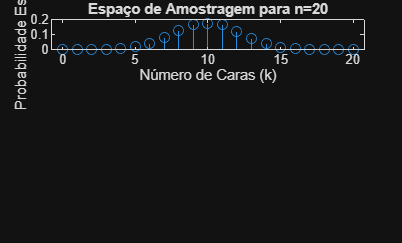

N = 1e5;     % Número de experiências
p = 0.5;     % Lançamento de moeda equilibrada
n = 20;      % Número de lançamentos
resultados = zeros(1, n+1);

for k = 0:n
    resultados(k+1) = estimarProbabilidade(p, n, k, N);
end

subplot(3,1,1); % Cria o primeiro de 3 gráficos
stem(0:n, resultados);
title('Espaço de Amostragem para n=20');
xlabel('Número de Caras (k)');
ylabel('Probabilidade Estipada');